# Problema 4

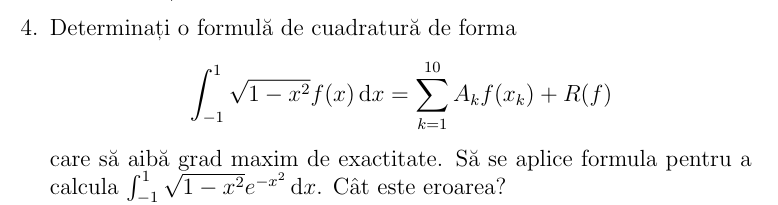

% PB1 - Cebisev 2
function [noduri, coeficienti] = gauss_chebyshev2(n)
    k = 1:n;
    noduri = cos(pi * k / (n + 1));
    coeficienti = pi / (n + 1) * sin(pi * k / (n + 1)).^2;
end

function [I, I_ex, eroare] = integrare_chebyshev2(f, n, a, b, precizie)
% Input:
%   f        - funcția f(x) fără pondere
%   n        - numărul de noduri
%   a, b     - capetele integralei (ideal [-1, 1])
%   precizie - (opțional) precizie numerică pentru calculul valorii exacte
%
% Output:
%   I        - valoarea aproximată a integralei
%   I_ex     - valoarea exactă (numerică)
%   eroare   - eroare absolută

   if nargin < 5
        precizie = NaN;
    end

    % Obtinem nodurile si coeficientii pentru [-1, 1]
    [t, A] = gauss_chebyshev2(n);

    % Daca intervalul nu este [-1, 1], aplicam schimbare de variabila
    if ~(a == -1 && b == 1)
        % x = ((b - a)/2) * t + (a + b)/2
        x = ((b - a)/2) * t + (a + b)/2;
        fx = f(x);  % evaluam functia in punctele transformate
        I = ((b - a)/2) * sum(A .* fx);
    else
        x = t;
        fx = f(x);
        I = sum(A .* fx);
    end

    % Valoare exactă (numerica) pentru comparatie
    if ~isnan(precizie)
        g = @(x) sqrt(1 - ((2*x - (b + a)) / (b - a)).^2) .* f(x); % schimbare inversă în densitate
        I_ex = integral(g, a, b, 'RelTol', precizie);
        eroare = abs(I - I_ex);
    else
        I_ex = NaN;
        eroare = NaN;
    end
end

% Functia f(x) din integrandul: ∫_{-1}^{1} sqrt(1 - x^2) * f(x) dx
f = @(x) exp(-x.^2);
n = 10;
a = -1;
b = 1;
eps = 1e-12;

[I, I_ex, err] = integrare_chebyshev2(f, n, a, b, eps);

fprintf("→ Cuadratura Gauss-Chebyshev II pe [%g, %g], n = %d\n", a, b, n);

→ Cuadratura Gauss-Chebyshev II pe [-1, 1], n = 10


fprintf("→ Valoare exactă (numerică): I_ex = %.10f\n", I_ex);

→ Valoare exactă (numerică): I_ex = 1.2589242566


fprintf("→ Aproximare cuadratură:     I ≈ %.10f\n", I);

→ Aproximare cuadratură:     I ≈ 1.2589242566


fprintf("→ Eroare absolută:            %.2e\n", err);

→ Eroare absolută:            2.63e-13



if abs(I) < 1e-14
    fprintf(" Integrala ≈ 0: functia este impara pe un interval simetric.\n");
end